# TNA010: Computer assignments 1

### Namn: Lovisa Svensson

### Datum: 2023-11-08

**Kompletterad: 2023-11-22**

## Problem 3

Code:

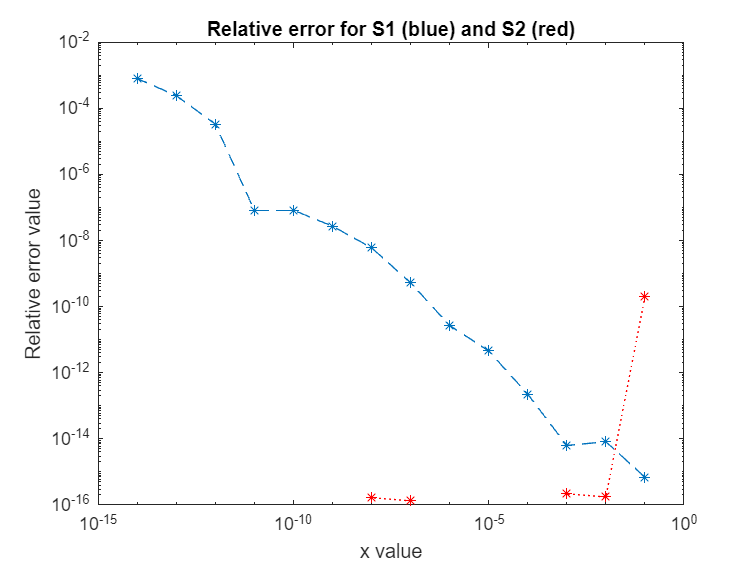

% Define arrays to be used
% The expression arrays are not really needed
clear
clf
xarray = zeros(14, 1);
y = zeros(14, 1);
s1 = zeros(14, 1);
s2 = zeros(14, 1);
rel_err_s1 = zeros(14, 1);
rel_err_s2 = zeros(14, 1);

% Calculate the relative error for every x from x = 10^-1 to 10^-14.
for i = 1:14
    xarray(i) = 10^(-i);
    x = xarray(i);

    % Use the expressions for the given x value
    y(i) = sinh(x);
    s1(i) = (exp(x)-exp(-x))/2;
    s2(i) = (x + (x^3)/factorial(3) + (x^5)/factorial(5));

    % Calculate relative errors for S1 and S2
    rel_err_s1(i) = (abs(s1(i) - y(i))) / abs(y(i));
    rel_err_s2(i) = (abs(s2(i) - y(i))) / abs(y(i));
end

% Logarithmic plot of the relative errors for S1 and S2
loglog(xarray, rel_err_s1, "--*");
title('Relative error for S1 (blue) and S2 (red)')
xlabel('x value')
ylabel('Relative error value') 
hold on
loglog(xarray, rel_err_s2, "r:*");

What I did here is to compute the relative errors by comparing S1 and S2 against y = sinh(x), which is to be regarded as the "true" value. I then plotted the relative errors for x values that are close to 0. My conclusion is that for S1, the approximation gets a worse relative error as x gets closer to 0, but for S2 the error stays about the same. The reason S1's error increases is because of catastrophic cancellation: as x approaches 0, both e^(x) and e^(-x) approach 1 and the difference between them is very small. The program can't capture this small difference correctly, leading to increasing rounding errors. S2 doesn't have this problem as it doesn't subtract anything.

## Problem 4

Code (written function is at the end):

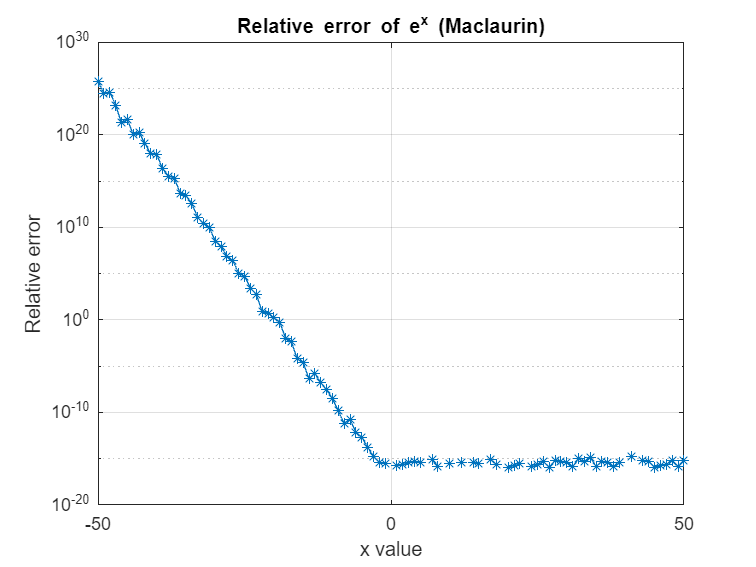

clear
clf

xvalues = zeros(100,1);
relative_error = zeros(101,1);

x = linspace(-50,50,101);

for i = 1:101
    calc = expmac(x(i));
    actual = exp(x(i));
    relative_error(i) = abs(calc - actual) / abs(actual);
end

%loglog(xvalues, relative_error, '-*');
semilogy(x, relative_error, '-*');
grid on
title('Relative error of e^x (Maclaurin)')
xlabel('x value')
ylabel('Relative error')

For positive values, the error is close to machine error, but the relative error starts increasing the lower x gets. The problem is related to cancellation, as the terms in the Maclaurin series alternate when x is negative. When these values are very close to each other, this will lead to cancellation and a larger relative error.

## Problem 5

a) The trick works like this: In base 10 the number 1/3 can't be stored fully, as the numerical value is 0.333333... and continues to infinity. 4/3 - 1 is 1/3. Multiplying this 1/3 with 3 doesn't completely return 1, as the fault from computing 0.33 is still there. The absolute value of this (1 +- error) - 1 is around 0, but not exactly, and this is the epsilon.

b) Code:

clear
epsilon = abs(3*(4/3 - 1) - 1)

epsilon = 2.2204e-16

single_e = abs(single(3)*(single(4)/single(3) - single(1)) - single(1))

single_e = single
1.1921e-07

It does work. Single precision deals with less decimals so it computes a different error value.

c) This would not work as in base 3 the value 1/3 can be stored directly. So 3*(4/3-1) = 3*(1/3) = 1 and the expression would correctly return a value of 0.

## Problem 6

Code a):

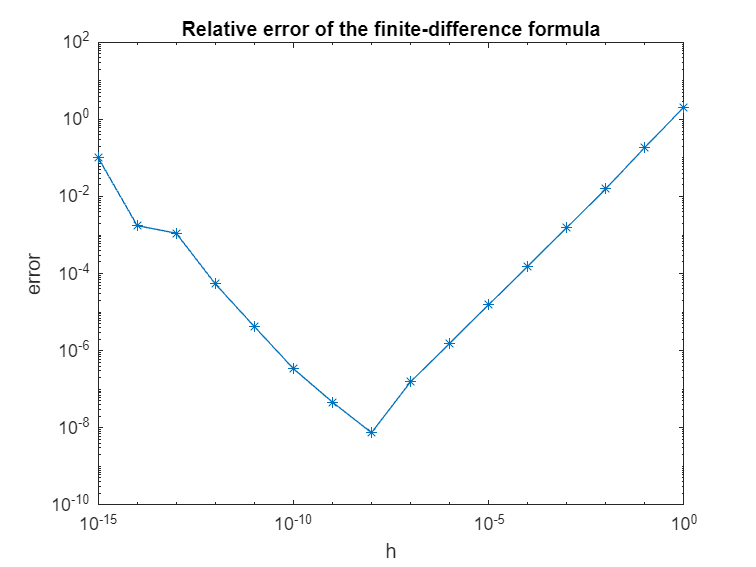

clear
clf
x = 1;

% Define arrays
% Sec_sq and fin_diff not really needed
fin_diff = zeros(16, 1);
sec_sq = zeros(16, 1);
h_values = zeros(16, 1);
error_values = zeros(16, 1);

% Loop through every h value to calculate relative error
for k = 1:16
    % Set up h
    h_values(k) = 10^(-(k-1));
    h = h_values(k);

    % Calculate results of the expressions
    fin_diff(k) = (tan(x+h) - tan(x)) / h;
    sec_sq(k) = (sec(x))^2;

    % Calculate relative error (compare finite difference against sec squared)
    error_values(k) = abs(fin_diff(k) - sec_sq(k)) / abs(sec_sq(k));
end

% Logarithmic plot of the error
loglog(h_values, error_values , '-*');
title('Relative error of the finite-difference formula')
xlabel('h')
ylabel('error')

Here, the finite difference formula is compared against sec^2(x) and the relative error is computed and plotted for every given h value. For calculating derivatives, the formula is meant for lim h -> 0, so the closer h gets to 0 the more accurate the formula should be, theoretically. This is shown in the right half of the plot where the relative error decreases as h gets closer to 0. However, after a certain point (the minimum value), the error increases again. These are computational errors that appear for values very close to 0 that is not connected to the theory of it.

Code b):

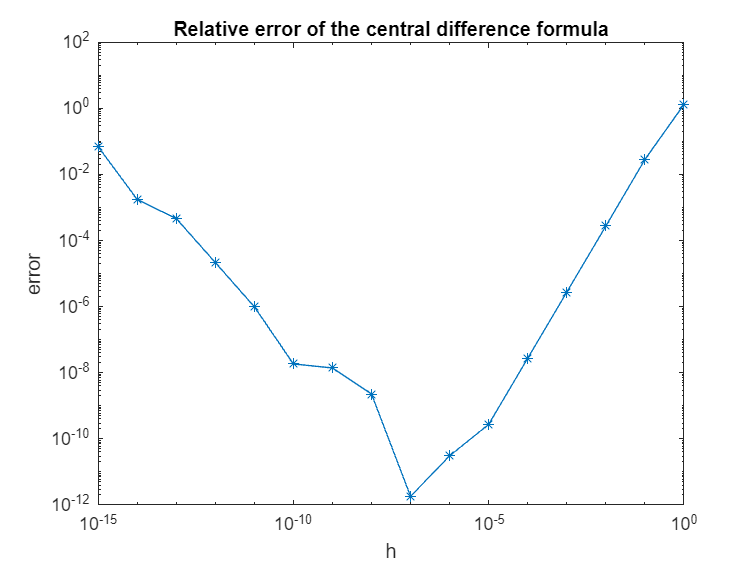

clear
clf
x = 1;

% Define arrays
% Sec_sq and fin_diff not really needed
cen_diff = zeros(16, 1);
sec_sq = zeros(16, 1);
h_values = zeros(16, 1);
error_values = zeros(16, 1);

% Loop through every h value to calculate relative error
for k = 1:16
    % Set up h
    h_values(k) = 10^(-(k-1));
    h = h_values(k);

    % Calculate results of the expressions
    cen_diff(k) = (tan(x+h) - tan(x-h)) / (2*h);
    sec_sq(k) = (sec(x))^2;

    % Calculate relative error (compare central difference against sec squared)
    error_values(k) = abs(cen_diff(k) - sec_sq(k)) / abs(sec_sq(k));
end

% Logarithmic plot of the error
loglog(h_values, error_values , '-*');
title('Relative error of the central difference formula')
xlabel('h')
ylabel('error')

## Function for problem 4

function new_sum = expmac(x)
old_term = 1;
new_sum = 1;
old_sum = 0;
n = 1;

% x = 0 stops the program
    while new_sum ~= old_sum
        old_sum = new_sum;

        new_term = old_term*x/n;
        new_sum = old_sum + new_term;

        old_term = new_term;
        n = n+1;
    end
end